clear 
close

% First load the dataset variables
load dataset3.mat

for i = 1:1900
    
    av_points = y_k_j(:,i,:);
    colsav = any(av_points ~= -1,1);
    num(i) = sum(colsav);
     
    
end

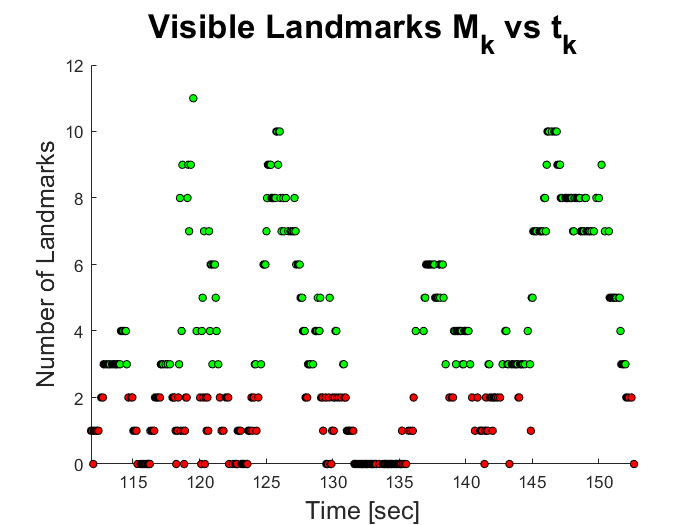

figure

%plot(t(1:1900),num(1:1900),'LineWidth',0.01, 'Color','k')
%hold on

for i = 1:1900
    
    if num(i) >= 3
        scatter(t(i),num(i),20,'MarkerEdgeColor','k',...
              'MarkerFaceColor','g',...
              'LineWidth',0.5)
    else
        scatter(t(i),num(i),20,'MarkerEdgeColor','k',...
              'MarkerFaceColor','r',...
              'LineWidth',0.005)
    end
    
    hold on
    
end
title('Visible Landmarks M_k vs t_k','FontSize',20)
xlabel('Time [sec]','FontSize',15)
ylabel('Number of Landmarks','FontSize',15)
%xlim([0,170])
xlim([t(1215),t(1714)])